# Mobile Robotics Exercise

## Mobile Robot Block

First, it is necessary to define the robot model that will be used. In the context of this project, the choice has been made to use the unicycle model:

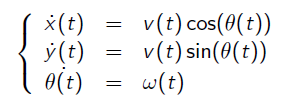

In this section, we proceed to define the key structural parameter, which is the robot's diameter. The control signals, on the other hand, will be determined in the section dedicated to the *Controller* block.

clear; close all; clc;

% MOBILE ROBOT
diameter = 5;

## Environment Block

In this phase, we design the predefined environment in which the robot will operate. Scroll down to see it.

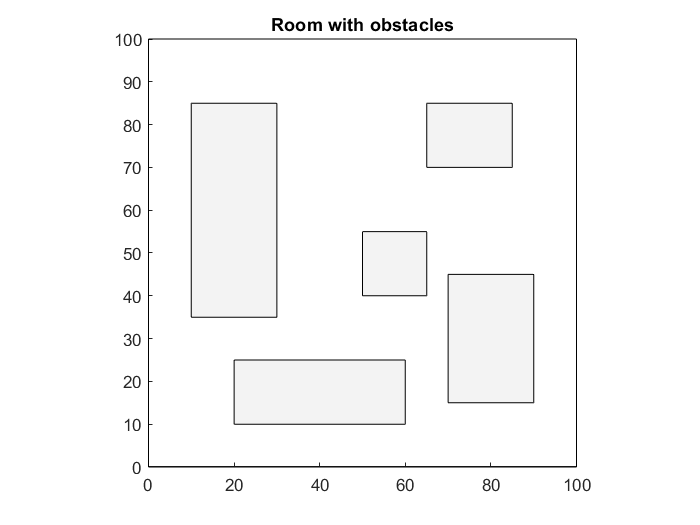

% ENVIRONMENT

% OBSTACLES
% obstacle i = [sw; se; nw; ne]
% room
obstacles = [0 0;100 0;0 100;100 100;];
% obstacle 1 in the room
obstacles = [obstacles;10 35;30 35; 10 85;30 85];
% obstacle 2 in the room
obstacles = [obstacles;20 10;60 10; 20 25;60 25];
% obstacle 3 in the room
obstacles = [obstacles;50 40;65 40; 50 55;65 55];
% obstacle 4 in the room
obstacles = [obstacles;70 15;90 15; 70 45;90 45];
% obstacle 5 in the room
obstacles = [obstacles;65 70;85 70; 65 85;85 85];

% Plot of the room with obstacles
figure(1); axis('equal'); axis([0 100 0 100]); title('Room with obstacles')
rectangle('Position', [obstacles(1,1) obstacles(1,2) ...
    obstacles(4,1)-obstacles(1,1) obstacles(4,2)-obstacles(1,2)]);
for i=5:4:length(obstacles)
    rectangle('Position', [obstacles(i,1) obstacles(i,2) ...
        obstacles(i+3,1)-obstacles(i,1) obstacles(i+3,2)-obstacles(i,2)], ...
        'FaceColor', '#f3f3f3');
end

% The following variable represents the vector of points 
% that form the boundaries of the obstacles.
[room]=Utility.Build_Room(obstacles);

#### Initial position, goal, and orientation selection

Follow the instructions in the command window to proceed.

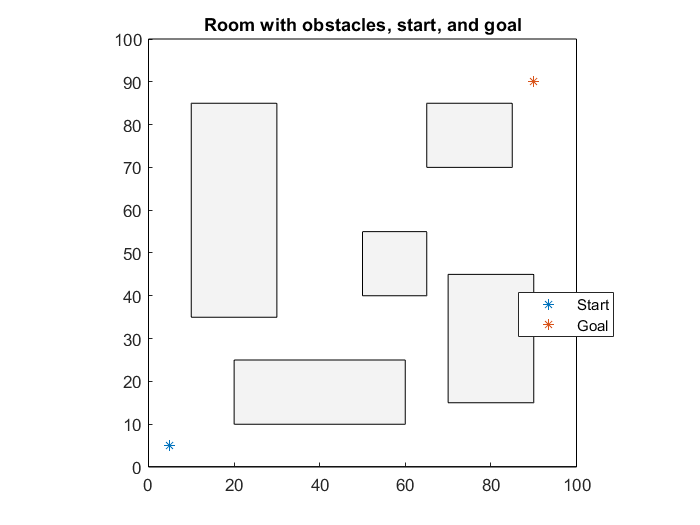

prompt1 = "Enter the values for the starting point 'SP=[x,y]', " + ...
"the goal 'G=[x,y]',\nand the final orientation 'thetaG=x' " + ...
"(expressed in radians) and press \nENTER:\n > SP = ";
SP = input(prompt1);
G = input(" > G = ");
thetaG = input(" > thetaG = ");

% Plot of the room with obstacles, start, and goal
figure(1); hold on;
title('Room with obstacles, start, and goal');
plot(SP(1),SP(2),'*'); plot(G(1),G(2),'*'); 
legend('Start','Goal','Location','best');

## Planner Block

At this point, both the environment and the task are known, so we can proceed with the trajectory planning.

To choose which planner to use, follow the instructions in the command window.

% PLANNER

clc; prompt2 = "Enter the number corresponding to the technique " + ...
    "you want to use and press ENTER:\n 1) Artificial Potential " + ...
    "Fields\n 2) Discrete Potential Fields\n 3) Voronoi Diagrams" + ...
    "\n 4) Visibility Graphs \n> ";
planner_selection = input(prompt2);
return
switch planner_selection
    case 1
        [path]=Planners.Artificial_Potential_Fields(SP,G,room,obstacles);
    case 2
        [path]=Planners.Discrete_Potential_Fields(SP,G,obstacles);
    case 3
        [path]=Planners.Voronoi_Diagrams(SP,G,room,obstacles);
    case 4
        [path]=Planners.Visibility_Graphs(SP,G,obstacles);
end

## Blocco Controller

### Trajectory Tracking

In questa sezione ci si occupa di progettare una legge di controllo per inseguire la traiettoria ottenuta al punto precedente.

Per scegliere quale legge di controllo utilizzare, seguire le istruzioni presenti nella command window.

% CONTROLLER - Trajectory Tracking

% Definizione della traiettoria di riferimento
P=polyfit(path(:,1),path(:,2),5);
x_star=@(t)(t);
y_star=@(t)(P(1)*t.^5 + P(2)*t.^4 + P(3)*t.^3 + P(4)*t.^2 ...
    + P(5)*t + P(6));
   
xd_star=@(t)(ones(size(t)));
yd_star=@(t)(5*P(1)*t.^4 + 4*P(2)*t.^3 + 3*P(3)*t.^2 + 2*P(4)*t + P(5));
theta_star=@(t)(atan2(yd_star(t),xd_star(t)));
   
xdd_star=@(t)(zeros(size(t)));
ydd_star=@(t)(20*P(1)*t.^3 + 12*P(2)*t.^2 + 6*P(3)*t + 2*P(4));

x0=SP(1)+2; y0=SP(2)+2; theta0=thetaG+pi/2;

clc; prompt3 = "Inserire il numero relativo alla legge di controllo" + ...
    " che si vuole \nutilizzare e premere INVIO:\n 1) Controllo " + ...
    "Lineare\n 2) Controllo Non Lineare\n 3) Input-Output Linearization\n> ";
scelta_legge = input(prompt3);

switch scelta_legge
    case 1
        % Controllo lineare
        a=0.2;
        if planner_selection==4
            a=1;
        end
        delta=0.99;
        f_robot=@(t,X)(Controllers.robot_control_lin(t,X, ...
            x_star,y_star,theta_star, ...
            xd_star,yd_star,xdd_star,ydd_star,a,delta));
    case 2
        % Controllo non lineare
        k1=@(vs,ws)(ones(size(vs)));
        k3=@(vs,ws)(ones(size(vs)));
        k2=0.03;
        if planner_selection==4
            k2=0.001;
        end
        f_robot=@(t,X)(Controllers.robot_control_NL(t,X, ...
            x_star,y_star,theta_star, ...
            xd_star,yd_star, ...
            xdd_star,ydd_star,k1,k2,k3));
    case 3
        % Feedback linearization
        k1=0.2;
        k2=0.2;
        b=0.5;
        f_robot=@(t,X)(Controllers.robot_control_FL(t,X, ...
            x_star,y_star, ...
            xd_star,yd_star,k1,k2,b));
end

Tsim=path(length(path))-1;

[t,evolution]=ode45(f_robot,[1,Tsim],[x0;y0;theta0]);

x=evolution(:,1);
y=evolution(:,2);
theta=(evolution(:,3));

% Plot della stanza con gli ostacoli "ingrassati" di 5 (raggio del robot) +
% il 10% del raggio
r = diameter + diameter*0.10;
Utilita.plot_ostacoli_ingrassati(obstacles,x0,y0,G,r);

% Plot della traiettoria di riferimento e della traiettoria del robot
plot(x,y,"LineWidth",2);
plot(x_star(t),y_star(t));
switch scelta_legge
    case 1
        title('Trajectory tracking - Controllo lineare');
    case 2
        title('Trajectory tracking - Controllo non lineare');
    case 3
        title('Trajectory tracking - Feedback linearization');
end
legend('Punto di partenza','Goal','Traiettoria del robot', ...
    'Traiettoria di riferimento','Location','best'); hold off;
% Plot degli andamenti delle variabili
if (scelta_legge==3)
    Utilita.plot_andamenti_1(t,x,x_star,y,y_star,theta,theta_star, ...
    scelta_legge,b);
else
    Utilita.plot_andamenti_1(t,x,x_star,y,y_star,theta,theta_star, ...
    scelta_legge);
end

### Posture regulation

% CONTROLLER - Posture Regulation

k1=1;
k2=10;
k3=10;

f_robot=@(t,X)(Controllers.complete_posture_regulation(t,X, ...
    [G(1);G(2);thetaG],k1,k2,k3));

x0=x(length(t));
y0=y(length(t));
theta0=theta(length(t));

[t2,evolution]=ode45(f_robot,[0,100],[x0;y0;theta0]);

x1=evolution(:,1);
y1=evolution(:,2);
theta1=(evolution(:,3));

% Plot della traiettoria ottenuta
Utilita.plot_ostacoli_ingrassati(obstacles,x0,y0,G,r);
plot(x1,y1,"LineWidth",2);
axis([G(1)-15 G(1)+15 G(2)-15 G(2)+15]);
title('Posture regulation');
legend('Punto di arrivo del traj. tracking','Goal','Traiettoria', ...
    'Location','best'); hold off;
% Plot degli andamenti delle variabili
Utilita.plot_andamenti_2(t2,x1,y1,G,theta1,thetaG);